# V11: single-car 3D visualization

Integrates V8 plant equations and practice 4 controllers without modifying them. The fourteen-corner circuit has a chicane, a 90-degree R4 m corner after a roughly 172 m straight, and a 70-degree R3.5 m corner. Maximum demands use rapid continuous transitions. The historical overview lists five caps, 15, 20, 25, 30 and 35 m/s; the executable configuration below determines the actual cases. Speed references use curvature and acceleration/braking bounds, continuous across closure. Short straights need not reach each cap. Results distinguish lap completion from leaving the lane. Original sources: CuatroruedasV8_bloqueo_ruedas.mlx and P4_seguimiento_trayectoria_ALUMNO.mlx.

% Source: CuatroruedasV8_bloqueo_ruedas.mlx | SHA256: 5502b64c9336f6cbfcc394f0d39e986e2266b3d37636013bea30260a9f8ffa1c
% Source: P4_seguimiento_trayectoria_ALUMNO.mlx | SHA256: 58965f692cf38b8a1928c7ddcf16276dcb8aee7fd3a043acc123b057dd832679
%% V11: one 35 m/s car with 3D visualization
% Standalone file. V8 physical functions and P4 controllers
% are included without changing their equations. It neither reads nor writes
% the originals and does not need external Ensayos helpers.
% Track geometry, the test integrator and plots are new.
% Includes curvature-based speed planning. Does not include ESC, ABS or TCS.

%% Original V8 parameters
p = struct(); 

p.m    = 230;      % mass [kg]
p.g    = 9.81;     % gravity [m/s^2]
p.rho  = 1.225;    % air density [kg/m^3]
p.Cd   = 1.0;      % aerodynamic coefficient
p.Af   = 1.1;      % frontal area [m^2]
p.fr  = 0.022;    % rolling-resistance coefficient
p.Fx_drive_max = 2500;   % maximum driving force [N]
p.Fx_brake_max = 5000;   % maximum braking force [N]
p.theta = 0;      % road inclination [rad]

% Define the parameters needed to describe the vehicle's
% lateral dynamics here.
p.ld = 0.765; % [m] CG to front axle, longitudinal distance
p.lt = 0.765; % [m] CG to rear axle, longitudinal distance
p.lyd = 0.600; % [m] CG to front wheels, lateral distance
p.lyt = 0.600; % [m] CG to rear wheels, lateral distance
p.hcg = 0.230; % [m] centre-of-gravity height
% Wheel coordinates relative to the CG
% Order: DI, DD, TI, TD
p.xw = [p.ld,p.ld,-p.lt,-p.lt];
p.L = p.ld+p.lt; 
p.yw = [p.lyd, -p.lyd, p.lyt, -p.lyt];
p.td = p.lyd + p.lyt;
p.tt = p.td; 
p.Iz = 130; % [kg m^2] yaw inertia
p.Cad = 35000; % [N/rad] front cornering stiffness
p.Cat = 50000; % [N/rad] rear cornering stiffness --> understeering vehicle
p.Caw = [p.Cad/2, p.Cad/2, p.Cat/2, p.Cat/2];
p.nCa = 0.8; 
p.mu_t = 1.5; % rear tyre friction
p.mu_d = 0.95*p.mu_t; % front tyre friction
p.muw = [p.mu_d, p.mu_d, p.mu_t, p.mu_t];
% Lateral adhesion loss under excess traction demand
p.Kslip = 3; % Rear-wheel lateral-loss intensity
% Time dynamics of lateral loss and recovery
p.tau_slip_loss = 0.03; % loss time constant [s]
p.tau_slip_rec  = 0.50; % recovery time constant [s]
% Adhesion loss under excess braking demand.
% Initial test values, awaiting calibration.
% Two braking modes: normal and approximate lock.
% Illustrative parameters awaiting experimental calibration.
p.brake_slide_ratio = 0.68; % mu_min / mu_base (high-speed limit)
p.v_brake_slide = 15;      % Speed scale [m/s]
p.brake_lock_on = 1.02;    % Entry: demand / nominal capacity
p.brake_lock_off = 0.90;   % Hysteretic exit
p.tau_brake_loss = 0.03;   % Transition to lock-mode target [s]
p.tau_brake_rec = 0.10;    % Recovery under partial brake relief [s]
p.tau_brake_release = 0.01;% Rapid full-release recovery: 95% in 30 ms

% Force allocation
p.Fzd0 = p.m*p.g*p.lt/p.L; % [N] initial front-axle vertical load
p.Fzt0 = p.m*p.g*p.ld/p.L; % [N] initial rear-axle vertical load
p.Fzw0 = [p.Fzd0/2, p.Fzd0/2, p.Fzt0/2, p.Fzt0/2]; % [N] initial vertical load per wheel
p.drive_w = [0, 0, 0.5, 0.5]; % Driving-force allocation during acceleration
p.brake_w = [0.3, 0.3, 0.2, 0.2]; % Longitudinal-force allocation during braking
p.kRoll = 0.5; % front share of roll moment (replace with a suspension model later)



%% P4 controllers and test configuration
p.Kp_v=800; p.Ki_v=200;
p.Ld0=2.0; p.kLd=0.3; p.delta_max=0.5;
p.dt=0.002;
ensayo.ancho=3.0;             % distance between track boundaries [m]
ensayo.pasoTrayectoria=0.25;  % maximum geometric spacing [m]
ensayo.pasoConos=3.0;         % approximate cone spacing [m]
ensayo.velocidades=35; % speed caps [m/s], not constant references
% Aggressive planning limits; plant limits are unchanged.
plan.ayMax=8.0;             % target lateral acceleration [m/s^2]
plan.axAcel=6.0;            % planned longitudinal acceleration [m/s^2]
plan.axFreno=8.0;           % positive planned deceleration [m/s^2]
plan.anticipacionPI=0.10;   % temporal reference anticipation [s]
% Speed-map comparison: plant and driver remain unchanged.
planBase=plan;
plan.ayMax=11.0;            % Higher corner speed: smaller reduction
plan.axFreno=12.0;          % Optimistic assumption: start braking later
plan.anticipacionPI=0.0;    % No extra controller anticipation

ensayo.errorAbandono=10;      % stop if tracking leaves the reference widely [m]

% Aggressive driver: maximum targets with rapid exponential application.
% 95% application in 90 ms accelerating and 60 ms braking.
conductor.tauAcel=0.030; conductor.tauFreno=0.020;
conductor.errorActivar=0.35; conductor.errorSoltar=0.05; % hysteresis [m/s]
ensayo.conductor=conductor;
ensayo.animar=false; % Set true to open the player after simulation.

%% Stress circuit: 14 corners, chicane and braking before a 90-degree turn
pista=generarCircuitoHibrido(ensayo);
centro=pista.centro; cono_izq=pista.conoIzq; cono_der=pista.conoDer;
fprintf('\nCircuit: %.2f m; width %.1f m; %d straights and %d corners.\n', pista.longitud,ensayo.ancho,height(pista.curvas),height(pista.curvas));


Circuito: 631.56 m; ancho 3.0 m; 14 rectas y 14 curvas.


disp(pista.curvas);

    Curva    Radio_m      Sentido         Tipo       CentroX_m    CentroY_m    Angulo_deg
    _____    _______    ___________    __________    _________    _________    __________

      1         12      "izquierda"    "exterior"           4          12         36.87  
      2          4      "izquierda"    "exterior"         176           4            90  
      3         12      "izquierda"    "exterior"         168          48            90  
      4          6      "izquierda"    "exterior"         161          54            90  
      5          5      "derecha"      "interior"         150          45            90  
      6          5      "derecha"      "interior"         135          45            90  
      7          9      "izquierda"    "e


%% Single car with V11 speed mapping: 35 m/s cap
p.v_set=35;
perfil=planificarVelocidad(pista,p.v_set,plan);
hist35=simularHibrido(p,pista,ensayo,perfil,plan);

Caso Vmax 35.0 m/s: vuelta completada, t=47.68 s, max |e|=0.776 m.


resultados={hist35}; perfiles={perfil};
resumen=resumirHibrido(resultados,ensayo); disp(resumen);

    Vmax_ms    VueltaCompleta    TiempoSimulado_s    ErrorMedio_m    ErrorRMS_m    ErrorMax_m    TiempoFueraCarril_pct    Saturacion_pct    Bloqueo_pct    PicoPlanificado_ms    PicoReal_ms    ErrorVelRMS_ms
    _______    ______________    ________________    ____________    __________    __________    _____________________    ______________    ___________    __________________    ___________    ______________

      35           true               47.68            0.14719         0.2384       0.77598                0                  78.629          19.869               35            

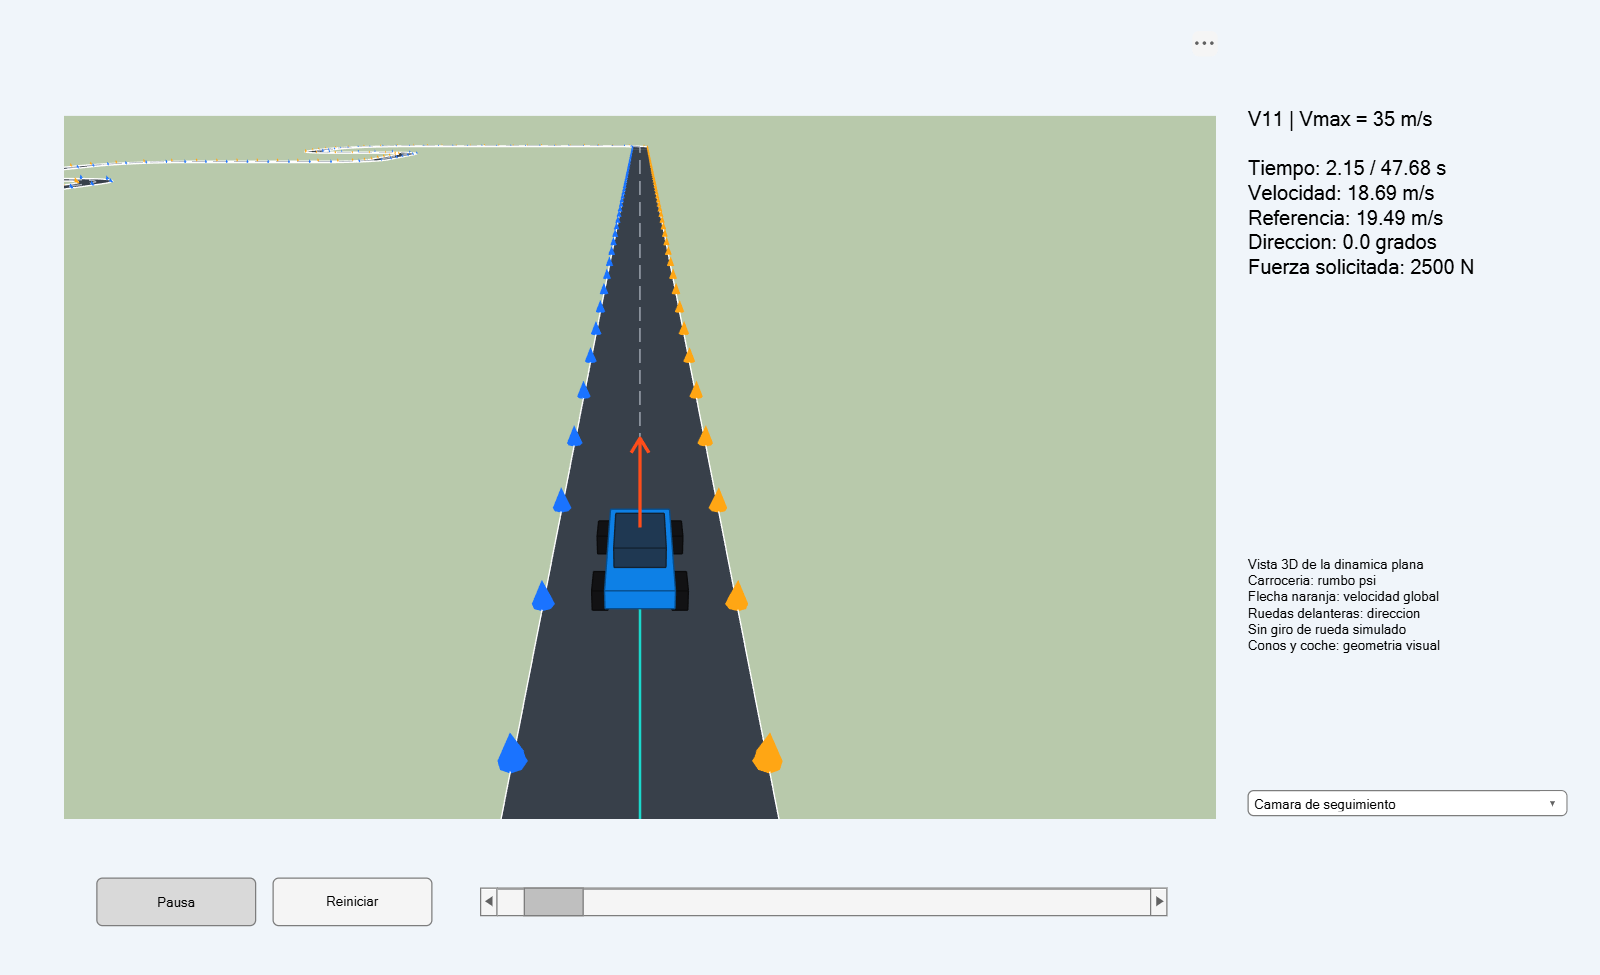


%% 3D visualization (dynamics remain planar)
% No roll, pitch, dynamic height or wheel rotation is simulated.
% Chase/overview camera, pause, restart and time slider.
op3D.reproducir=true;
fig3D=animarVehiculo3D(hist35,pista,p,op3D);


%% Physical functions and controllers copied from the originals
function [z_next, tele] = pasoDinamico(z, u, p, dt)
    % Complete state (20x1), wheel order DI, DD, TI, TD:
    % 1:6   X, Y, psi, vx, vy, r (motion)
    % 7:8   previous ax, ay (quasi-static transfer)
    % 9:12  eta_slip (lateral adhesion memory)
    % 13:16 eta_brake (braking-capacity memory)
    % 17:20 bloqueo_w (discrete mode, 0 or 1)
    if ~isvector(z) || numel(z) ~= 20
        error('pasoDinamico:EstadoInvalido', 'The dynamic state requires 20 components; initialize its memory.');
    end
    z = z(:);
    ax_prev = z(7);
    ay_prev = z(8);
    eta_prev = z(9:12).';
    eta_brake_prev = z(13:16).';
    bloqueo_prev = logical(z(17:20).');
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    vy = z(5);
    r = z(6);
    L = p.ld + p.lt;
    xw = p.xw;
    yw = p.yw;


    % vx_c = max(vx, 1.0); % corrected speed to avoid division by zero,
    % disabled now that the model uses atan2

    
    %% 1. Individual wheel kinematics

    delta_w = [delta, delta, 0, 0];

    % Wheel-centre velocities in chassis coordinates
    vxw = vx - r .* p.yw;
    vyw = vy + r .* p.xw;

    % Velocities projected into individual wheel coordinates
    vxw_local =  vxw .* cos(delta_w) + vyw .* sin(delta_w);
    vyw_local = -vxw .* sin(delta_w) + vyw .* cos(delta_w);

    % Individual slip angles
    alpha_w = delta_w-atan2(vyw_local, vxw_local);

    %% Define adhesion limits
    % Longitudinal transfer between axles
    dFzx = p.m*ax_prev*p.hcg/p.L;

    % Lateral transfer within each axle
    dFzyd = p.kRoll*p.m*ay_prev*p.hcg/p.td;
    dFzyt = (1-p.kRoll)*p.m*ay_prev*p.hcg/p.tt;

    % Order: DI, DD, TI, TD
    Fzw = p.Fzw0 + [-dFzx/2, -dFzx/2, dFzx/2, dFzx/2] + [-dFzyd, dFzyd, -dFzyt,dFzyt];
    % Longitudinal grip
    % Lateral forces per wheel
    Caw = p.Caw .* (Fzw ./ p.Fzw0).^p.nCa;
    Fyw = Caw .* alpha_w;

    % Longitudinal driving-force allocation per wheel
    if Fx >= 0
        Fxw_sol = Fx .* p.drive_w;
    else
        Fxw_sol = Fx .* p.brake_w;
    end

    %% Normal braking and approximate locking with memory
    Fmax_peak_w = p.muw .* Fzw;
    demanda_freno_w = max(0,-Fxw_sol);
    ratio_freno_w = demanda_freno_w ./ max(Fmax_peak_w,eps);
    s_brake_w = max(0,ratio_freno_w-1);

    % Hysteresis relative to the NOMINAL limit, not the reduced limit.
    bloqueo_w = logical(bloqueo_prev);
    bloqueo_w(ratio_freno_w > p.brake_lock_on) = true;
    bloqueo_w(ratio_freno_w < p.brake_lock_off) = false;
    freno_suelto_w = (demanda_freno_w == 0);
    bloqueo_w(freno_suelto_w) = false;

    % Assumed locked wheel: sliding speed equals local forward speed.
    % Capacity approaches mu_base at low v and mu_min at high v.
    eta_bloq_vel = p.brake_slide_ratio + (1-p.brake_slide_ratio).*exp(-abs(vxw_local)/p.v_brake_slide);
    eta_brake_obj = ones(1,4);
    eta_brake_obj(bloqueo_w) = eta_bloq_vel(bloqueo_w);

    eta_brake = eta_brake_prev;
    for i = 1:4
        if freno_suelto_w(i)
            tau = p.tau_brake_release;
        elseif bloqueo_w(i)
            tau = p.tau_brake_loss;
        else
            tau = p.tau_brake_rec;
        end
        factor = 1-exp(-dt/tau);
        eta_brake(i) = eta_brake_prev(i) + factor*(eta_brake_obj(i)-eta_brake_prev(i));
    end
    eta_brake = max(p.brake_slide_ratio,min(1,eta_brake));

%% Friction circle with effective capacity

% The loss modifies the combined Fx/Fy limit only once.
Fmax_w = eta_brake .* Fmax_peak_w;

% Extension of the existing lock mode (simplified model):
% unit longitudinal factor: preserves the calculated mu_eff*Fz limit.
% zero lateral factor: removes Fy demand BEFORE circle saturation.
factor_x_bloqueo = ones(1,4);
factor_y_bloqueo = double(~bloqueo_w);
Fyw = factor_y_bloqueo .* Fyw;

Fres_w = hypot(Fxw_sol,Fyw);
lambda_w = min(ones(1,4), ...
    Fmax_w ./ max(Fres_w,eps));

Fxw = lambda_w .* Fxw_sol;
Fyw = lambda_w .* Fyw;

    
    %% Progressive lateral adhesion loss and recovery

    % Excess longitudinal demand relative to adhesion
    s_w = max(0, abs(Fxw_sol) ./ max(Fmax_w,eps) - 1);

    % Target lateral-capacity factor
    eta_obj = ones(1,4);

    % Additional loss is only triggered during driving
    if Fx > 0
        eta_obj(3:4) = 1 ./ (1 + p.Kslip .* s_w(3:4));
    end

    % Adhesion state inherited from the previous step
    eta_slip = eta_prev;

    % Rear-wheel time update
    for i = 3:4

        % Rapid loss or slow recovery
        if eta_obj(i) < eta_prev(i)
            tau = p.tau_slip_loss;
        else
            tau = p.tau_slip_rec;
        end

        % Stable exponential integration
        factor = 1 - exp(-dt/tau);

        eta_slip(i) = eta_prev(i) + factor * (eta_obj(i) - eta_prev(i));

    end

    % Bound the factor to its physically defined interval
    eta_slip = max(0,min(1,eta_slip));

    % Rear lateral-force reduction
    Fyw(3:4) = eta_slip(3:4) .* Fyw(3:4);

    % In lock mode, braking acts exclusively along CHASSIS X.
    % Removing only local Fy would still allow steering through Fx*sin(delta).
    % Outside lock mode, retain the original transformation.
    % This is a simplified restriction, not isotropic locked-wheel friction.
    delta_fuerza_w = delta_w;
    delta_fuerza_w(bloqueo_w) = 0;
    Fxw_chasis = Fxw .* cos(delta_fuerza_w) - Fyw .* sin(delta_fuerza_w);
    Fyw_chasis = Fxw .* sin(delta_fuerza_w) + Fyw .* cos(delta_fuerza_w);

    % Resultant forces and moment
    SumFx = sum(Fxw_chasis); % Total longitudinal force
    SumFy = sum(Fyw_chasis); % Total lateral force
    SumMz = sum(p.xw .* Fyw_chasis - p.yw .* Fxw_chasis); % Yaw moment about the CG

    % Telemetry: current-step data without changing forces or dynamics
    tele.alpha_w = alpha_w;
    tele.Fxw = Fxw;
    tele.Fyw = Fyw;
    tele.Fzw = Fzw;
    tele.Caw = Caw;
    tele.Mzw = p.xw .* Fyw_chasis - p.yw .* Fxw_chasis;
    tele.Mz_long = sum(p.xw .* (Fxw .* sin(delta_fuerza_w)) - p.yw .* (Fxw .* cos(delta_fuerza_w)));
    tele.Mz_lat = SumMz - tele.Mz_long;
    tele.lambda_w = lambda_w;
    tele.Fmax_w = Fmax_w;
    tele.s_w = s_w;
    tele.eta_slip = eta_slip;
    tele.eta_obj = eta_obj;
    tele.Fmax_peak_w = Fmax_peak_w;
    tele.s_brake_w = s_brake_w;
    tele.eta_brake = eta_brake;
    tele.eta_brake_obj = eta_brake_obj;
    tele.bloqueo_w = bloqueo_w;
    tele.mu_eff_w = p.muw .* eta_brake;
    tele.factor_x_bloqueo = factor_x_bloqueo;
    tele.factor_y_bloqueo = factor_y_bloqueo;
    tele.delta_fuerza_w = delta_fuerza_w;
    tele.Fxw_chasis = Fxw_chasis;
    tele.Fyw_chasis = Fyw_chasis;

    % Longitudinal dynamics (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    
    % equations of motion
    ax_fis = (SumFx - Ra - sign(vx)*Rr - Rg)/p.m;
    ay_fis = SumFy/p.m;
    ax  = ax_fis + vy*r; % retain centripetal coupling
    ay = ay_fis - vx*r; 
    dr = SumMz/p.Iz;   
    tele.ax = ax_fis;
    tele.ay = ay_fis;

    vx_next = max(vx + ax*dt,0);
    vy_next = vy + ay*dt; 
    r_next = r + dr*dt;
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next; ...
        ax_fis; ay_fis; eta_slip(:); eta_brake(:); double(bloqueo_w(:))]; 
end

function z = inicializarEstadoDinamico(z)
    % Preserve memory when a complete state is supplied.
    z = z(:);
    if numel(z) == 6
        z = [z; zeros(2,1); ones(4,1); ones(4,1); zeros(4,1)];
    elseif numel(z) ~= 20
        error('Dynamic state: 6 or 20 components are required.');
    end
end

function [Fx, e_int] = controlVelocidadSimple(v_ref, vx, e_int, dt, p)
    e = v_ref - vx;  e_int = e_int + e*dt;
    Fx = p.Kp_v*e + p.Ki_v*e_int;
    Fx = min(max(Fx, -p.Fx_brake_max), p.Fx_drive_max);
end

function [delta, mem] = controlLateral(est, path, p, mem)
    x = est.X; y = est.Y; psi = est.psi; vx = est.vx;
    L = p.ld + p.lt;
    Ld = p.Ld0 + p.kLd*max(vx, 0);

    % Extract the target point where the lookahead distance intersects
    % the reference path.
    [tx, ty, mem.idx] = buscarPuntoAdelante(path, x, y, Ld, mem.idx);

    % calculate geometry

    alpha = atan2(ty-y,tx-x) -psi;
    alpha = atan2(sin(alpha), cos(alpha)); % normalize steering to [-pi,pi]
    delta = atan2(2*L*sin(alpha),Ld);

    delta = max(min(delta, p.delta_max), -p.delta_max);
end

function [tx, ty, idx] = buscarPuntoAdelante(path, x, y, Ld, idx)
% Return the target point and updated index.
    N = size(path,1);
    
    d2 = (path(:,1)-x).^2 + (path(:,2)-y).^2; % after deviation, re-anchor the index to the nearest point
    [~, icerca] = min(d2);
    idx = icerca;

    for step = 0:N % advance along the path until reaching Ld
        j = mod(idx-1+step,N) +1;
        if hypot(path(j,1)-x, path(j,2)-y) >= Ld
            tx = path(j,1);  ty = path(j,2);  idx = j;  return;
        end
    end
    j = mod(idx-1+round(N/10), N) + 1; % if no point is far enough, use the furthest available point ahead
    tx = path(j,1);  ty = path(j,2);  idx = j;
end

function e_ct = errorLateral(x, y, path) % positive e means left of the reference path
    d2 = (path(:,1)-x).^2 + (path(:,2)-y).^2;
    [~,i] = min(d2);  j = mod(i, size(path,1)) + 1;
    tang = atan2(path(j,2)-path(i,2), path(j,1)-path(i,1));
    dx = x-path(i,1); dy = y-path(i,2);
    e_ct = -sin(tang)*dx + cos(tang)*dy;
end

%% New geometry: rounded polygon with an inward section
function pista=generarCircuitoHibrido(cfg)
% Corner 2 turns 90 degrees after a straight of about 172 m.
% Corners 4-5: left-right chicane returning to a westward heading.
% Corner 12: exactly 70 degrees, radius 3.5 m.
vertices=[0 0;180 0;180 60;155 60;155 40;130 40;130 75; ...
    100 75;100 57;78 57;78 100;0 100; ...
    40*cosd(250) 100+40*sind(250);-40 30];
radios=[12 4 12 6 5 5 9 8 5 5 10 3.5 10 12]';
n=size(vertices,1); entrada=zeros(n,2); salida=entrada; centros=entrada;
angulos=zeros(n,1); giros=zeros(n,1);
for i=1:n
    ant=mod(i-2,n)+1; sig=mod(i,n)+1;
    a=vertices(i,:)-vertices(ant,:); a=a/norm(a);
    b=vertices(sig,:)-vertices(i,:); b=b/norm(b);
    giros(i)=atan2(a(1)*b(2)-a(2)*b(1),dot(a,b));
    d=radios(i)*tan(abs(giros(i))/2);
    entrada(i,:)=vertices(i,:)-d*a; salida(i,:)=vertices(i,:)+d*b;
    centros(i,:)=entrada(i,:)+sign(giros(i))*radios(i)*[-a(2) a(1)];
    angulos(i)=atan2(entrada(i,2)-centros(i,2),entrada(i,1)-centros(i,1));
end
xy=salida(1,:); tangente=[1 0]; curvatura=0;
for iter=1:n
    i=mod(iter,n)+1; ant=mod(i-2,n)+1;
    desde=salida(ant,:); hasta=entrada(i,:);
    tramo=hasta-desde; longitud=norm(tramo); direccion=tramo/longitud;
    assert(dot(tramo,vertices(i,:)-vertices(ant,:))>0,'Corner radii encroach on a straight segment.');
    np=max(1,ceil(longitud/cfg.pasoTrayectoria));
    q=(1:np)'/np;
    xy=[xy;desde+q.*tramo]; %#ok<AGROW>
    tangente=[tangente;repmat(direccion,np,1)]; %#ok<AGROW>
    curvatura=[curvatura;zeros(np,1)]; %#ok<AGROW>
    np=max(2,ceil(abs(giros(i))*radios(i)/cfg.pasoTrayectoria));
    theta=angulos(i)+giros(i)*(1:np)'/np;
    xy=[xy;centros(i,:)+radios(i)*[cos(theta) sin(theta)]]; %#ok<AGROW>
    tangente=[tangente;sign(giros(i))*[-sin(theta) cos(theta)]]; %#ok<AGROW>
    curvatura=[curvatura;repmat(sign(giros(i))/radios(i),np,1)]; %#ok<AGROW>
end
assert(norm(xy(end,:)-xy(1,:))<1e-9,'The circuit does not close.');
xy(end,:)=[]; tangente(end,:)=[]; curvatura(end)=[];
normal=[-tangente(:,2) tangente(:,1)];
s=[0;cumsum(vecnorm(diff(xy),2,2))];
longitud=s(end)+norm(xy(end,:)-xy(1,:));
izq=xy+cfg.ancho/2*normal; der=xy-cfg.ancho/2*normal;
sConos=(0:cfg.pasoConos:longitud-1e-9)';
pista.centro=xy; pista.s=s; pista.longitud=longitud;
pista.tangente=tangente; pista.curvatura=curvatura;
pista.bordeIzq=izq; pista.bordeDer=der;
pista.conoIzq=interp1([s;longitud],[izq;izq(1,:)],sConos);
pista.conoDer=interp1([s;longitud],[der;der(1,:)],sConos);
pista.segmentoA=xy; pista.segmentoB=circshift(xy,-1,1);
pista.segmentoD=pista.segmentoB-pista.segmentoA;
pista.segmentoL=vecnorm(pista.segmentoD,2,2);
sentido=repmat("left",n,1); sentido(giros<0)="right";
tipo=repmat("outside",n,1); tipo(giros<0)="inside";
pista.curvas=table((1:n)',radios,sentido,tipo,centros(:,1),centros(:,2), ...
    'VariableNames',{'Curva','Radio_m','Sentido','Tipo','CentroX_m','CentroY_m'});
pista.curvas.Angulo_deg=abs(rad2deg(giros));
pista.rectaAntes90_m=norm(entrada(2,:)-salida(1,:));
pista.chicane=[4 5];
end

function h=simularHibrido(p,pista,cfg,perfil,plan)
dt=p.dt; Tmax=max(90,2*pista.longitud/min(perfil.v)); N=ceil(Tmax/dt);
psi0=atan2(pista.tangente(1,2),pista.tangente(1,1));
vInicial=0; % Start from rest to check rapid application
z=inicializarEstadoDinamico([pista.centro(1,:)';psi0;vInicial;0;0]);
mem.idx=1; e_int=0; avance=0; sPrev=0; distancia=0;
memConductor.Fx=0; memConductor.modo=0;
h.t=zeros(N,1); h.z=zeros(N,20); h.delta=zeros(N,1); h.Fx_sol=zeros(N,1);
h.ect=zeros(N,1); h.ect_P4=zeros(N,1); h.s=zeros(N,1); h.distancia=zeros(N,1);
h.r_ref=zeros(N,1); h.ax=zeros(N,1); h.ay=zeros(N,1);
h.vref=zeros(N,1); h.vperfil=zeros(N,1);
h.Fx_obj=zeros(N,1); h.modoConductor=zeros(N,1);
campos={'Fxw','Fyw','Fzw','Fmax_w','Fmax_peak_w','lambda_w','eta_brake','eta_slip','Caw','bloqueo_w'};
for j=1:numel(campos), h.(campos{j})=zeros(N,4); end
h.completa=false; h.motivo="time limit";
for k=1:N
    [ect,sActual,idx]=proyectarCircuito(z(1:2)',pista);
    ds=sActual-sPrev;
    if ds < -pista.longitud/2, ds=ds+pista.longitud; end
    if ds > pista.longitud/2, ds=ds-pista.longitud; end
    avance=avance+ds; sPrev=sActual;
    est.X=z(1); est.Y=z(2); est.psi=z(3); est.vx=z(4); est.vy=z(5); est.r=z(6);
    [delta,mem]=controlLateral(est,pista.centro,p,mem);
    % Slight reference anticipation compensates PI delay.
    % Pure Pursuit geometric lookahead remains independent.
    vPerfil=consultarPerfil(perfil,sActual);
    sConsulta=sActual+max(z(4),0)*plan.anticipacionPI;
    vRef=min(p.v_set,consultarPerfil(perfil,sConsulta));
    [Fx,e_int,memConductor,FxObj]=controlConductorAgresivo( ...
        vRef,z(4),e_int,dt,p,cfg.conductor,memConductor);
    [zNext,tele]=pasoDinamico(z,[Fx;delta],p,dt);
    if ~isreal(zNext) || any(~isfinite(zNext)) || ~isreal(tele.Fzw) || any(tele.Fzw<0)
        if k==1, error('No valid plant step is available.'); end
        h.motivo="numerical limit or negative wheel load";
        k=k-1; break % Retain only valid steps without correcting the physics.
    end
    h.t(k)=(k-1)*dt; h.z(k,:)=z'; h.delta(k)=delta; h.Fx_sol(k)=Fx;
    h.ect(k)=ect; h.ect_P4(k)=errorLateral(z(1),z(2),pista.centro);
    h.s(k)=avance; h.distancia(k)=distancia;
    h.r_ref(k)=z(4)*pista.curvatura(idx);
    h.ax(k)=tele.ax; h.ay(k)=tele.ay;
    h.vref(k)=vRef; h.vperfil(k)=vPerfil;
    h.Fx_obj(k)=FxObj; h.modoConductor(k)=memConductor.modo;
    for j=1:numel(campos), h.(campos{j})(k,:)=tele.(campos{j}); end
    if avance>=pista.longitud && distancia>0.9*pista.longitud
        h.completa=true; h.motivo="lap completed"; break
    end
    if abs(ect)>cfg.errorAbandono
        h.motivo="tracking error exceeded 10 m"; break
    end
    distancia=distancia+norm(zNext(1:2)-z(1:2)); z=zNext;
end
camposRecortar=[{'t','z','delta','Fx_sol','ect','ect_P4','s','distancia','r_ref','ax','ay','vref','vperfil','Fx_obj','modoConductor'},campos];
for j=1:numel(camposRecortar), h.(camposRecortar{j})=h.(camposRecortar{j})(1:k,:); end
h.v_set=p.v_set;
h.perfil=perfil;
h.aprov_long=abs(h.Fxw)./max(h.Fmax_peak_w,eps);
h.aprov_lat=abs(h.Fyw)./max(h.Fmax_peak_w,eps);
h.aprov_total=hypot(h.Fxw,h.Fyw)./max(h.Fmax_w,eps);
h.fueraCarril=abs(h.ect)>cfg.ancho/2;
fprintf('Case Vmax %.1f m/s: %s, t=%.2f s, max |e|=%.3f m.\n', ...
    p.v_set,h.motivo,h.t(end),max(abs(h.ect)));
end

function [ect,sActual,idx]=proyectarCircuito(pos,pista)
rel=pos-pista.segmentoA;
q=sum(rel.*pista.segmentoD,2)./pista.segmentoL.^2;
q=min(max(q,0),1);
pie=pista.segmentoA+q.*pista.segmentoD;
[~,idx]=min(sum((pos-pie).^2,2));
d=pos-pie(idx,:); tang=pista.segmentoD(idx,:)/pista.segmentoL(idx);
ect=-tang(2)*d(1)+tang(1)*d(2);
sActual=mod(pista.s(idx)+q(idx)*pista.segmentoL(idx),pista.longitud);
end

function tabla=resumirHibrido(resultados,cfg)
n=numel(resultados); velocidad=zeros(n,1); completa=false(n,1); tiempo=velocidad;
errorMedio=velocidad; errorRMS=velocidad; errorMax=velocidad;
fuera=velocidad; saturacion=velocidad; bloqueo=velocidad;
for i=1:n
    h=resultados{i}; velocidad(i)=h.v_set; completa(i)=h.completa; tiempo(i)=h.t(end);
    errorMedio(i)=mean(abs(h.ect)); errorRMS(i)=sqrt(mean(h.ect.^2));
    errorMax(i)=max(abs(h.ect)); fuera(i)=100*mean(abs(h.ect)>cfg.ancho/2);
    saturacion(i)=100*mean(any(h.lambda_w<1-1e-6,2));
    bloqueo(i)=100*mean(any(h.bloqueo_w~=0,2));
end
tabla=table(velocidad,completa,tiempo,errorMedio,errorRMS,errorMax,fuera,saturacion,bloqueo, ...
    'VariableNames',{'Vmax_ms','VueltaCompleta','TiempoSimulado_s','ErrorMedio_m', ...
    'ErrorRMS_m','ErrorMax_m','TiempoFueraCarril_pct','Saturacion_pct','Bloqueo_pct'});
tabla.PicoPlanificado_ms=cellfun(@(h)max(h.perfil.v),resultados);
tabla.PicoReal_ms=cellfun(@(h)max(h.z(:,4)),resultados);
tabla.ErrorVelRMS_ms=cellfun(@(h)sqrt(mean((h.vref-h.z(:,4)).^2)),resultados);
end

function mostrarHibrido(resultados,pista,cfg,p)
colores=lines(numel(resultados)); ruedas={'DI','DD','TI','TD'};
figure('Name','Hybrid - circuit and trajectories','Color','w','Position',[80 80 1200 800]);
hold on; axis equal; grid on;
plot(pista.conoIzq(:,1),pista.conoIzq(:,2),'o','Color',[0 .3 .8],'MarkerSize',4,'DisplayName','Left cones');
plot(pista.conoDer(:,1),pista.conoDer(:,2),'o','Color',[.9 .7 0],'MarkerSize',4,'DisplayName','Right cones');
plot([pista.centro(:,1);pista.centro(1,1)],[pista.centro(:,2);pista.centro(1,2)],'k:','DisplayName','Reference');
for i=1:numel(resultados)
    h=resultados{i}; plot(h.z(:,1),h.z(:,2),'Color',colores(i,:),'LineWidth',1.5, ...
        'DisplayName',sprintf('Vmax %.0f m/s: %s',h.v_set,h.motivo));
end
for i=1:height(pista.curvas)
    text(pista.curvas.CentroX_m(i),pista.curvas.CentroY_m(i), ...
        sprintf('R%d=%g m',i,pista.curvas.Radio_m(i)),'FontSize',9);
end
plot(pista.centro(1,1),pista.centro(1,2),'ks','MarkerFaceColor','g','DisplayName','Start / finish');
xlabel('X [m]'); ylabel('Y [m]'); title('Stress circuit: 14 corners, chicane and high-speed straight');
legend('Location','bestoutside');

figure('Name','Hybrid - tracking and controls','Color','w','Position',[90 90 1250 800]);
tiledlayout(2,2,'TileSpacing','compact');
for panel=1:4
    nexttile; hold on; grid on;
    for i=1:numel(resultados)
        h=resultados{i}; etiqueta=sprintf('Vmax %.0f m/s',h.v_set);
        if panel==1, y=h.z(:,4); elseif panel==2, y=h.ect;
        elseif panel==3, y=rad2deg(h.delta); else, y=h.z(:,6); end
        plot(h.t,y,'Color',colores(i,:),'LineWidth',1.1,'DisplayName',etiqueta);
    end
    xlabel('Time [s]'); legend('Location','best');
    if panel==1, title('Longitudinal speed'); ylabel('v_x [m/s]');
    elseif panel==2
        yline(cfg.ancho/2,'k--','CG boundary','HandleVisibility','off');
        yline(-cfg.ancho/2,'k--','HandleVisibility','off'); title('Lateral error'); ylabel('e [m]');
    elseif panel==3
        yline(rad2deg(p.delta_max),'k:','Limit','HandleVisibility','off');
        yline(-rad2deg(p.delta_max),'k:','HandleVisibility','off'); title('Requested steering'); ylabel('delta [degrees]');
    else, title('Yaw rate'); ylabel('r [rad/s]'); end
end

for i=1:numel(resultados)
    h=resultados{i};
    figure('Name',sprintf('Hybrid - tyres %.0f m/s',h.v_set),'Color','w','Position',[100 100 1250 850]);
    tiledlayout(3,2,'TileSpacing','compact');
    nexttile; plot(h.t,h.Fzw,'LineWidth',1); grid on; ylabel('F_z [N]'); title('Vertical load'); legend(ruedas,'Location','best');
    nexttile; plot(h.t,h.aprov_long,'LineWidth',1); grid on; ylabel('|F_x| / (mu_{base}F_z)'); title('Longitudinal utilization');
    nexttile; plot(h.t,h.aprov_lat,'LineWidth',1); grid on; ylabel('|F_y| / (mu_{base}F_z)'); title('Lateral utilization');
    nexttile; plot(h.t,h.eta_brake,'LineWidth',1); grid on; ylabel('mu_{ef} / mu_{base}'); ylim([0 1.05]); title('Braking capacity');
    nexttile; plot(h.t,h.eta_slip,'LineWidth',1); grid on; ylabel('eta_{slip}'); ylim([0 1.05]); title('Lateral factor under traction');
    nexttile; stairs(h.t,h.bloqueo_w,'LineWidth',1); grid on; ylabel('Modo 0 / 1'); ylim([-0.05 1.05]); title('Approximate lock mode');
    for ax=findall(gcf,'Type','axes')', xlabel(ax,'Time [s]'); end
    sgtitle(sprintf('Vmax %.0f m/s: %s',h.v_set,h.motivo));
end
end


%% Speed planner and additional results
function perfil=planificarVelocidad(pista,vMax,cfg)
% Periodic profile: curvature limit with backward/forward passes.
validateattributes(vMax,{'numeric'},{'scalar','positive','finite'});
validateattributes(cfg.ayMax,{'numeric'},{'scalar','positive','finite'});
validateattributes(cfg.axAcel,{'numeric'},{'scalar','positive','finite'});
validateattributes(cfg.axFreno,{'numeric'},{'scalar','positive','finite'});
kappa=abs(pista.curvatura(:)); ds=pista.segmentoL(:); n=numel(kappa);
vLim=vMax*ones(n,1); curva=kappa>1e-9;
vLim(curva)=min(vMax,sqrt(cfg.ayMax./kappa(curva)));
v2=vLim.^2;
converge=false;
for iter=1:200
    anterior=v2;
    % Backward: reach the next point within the deceleration bound.
    for i=n:-1:1
        j=mod(i,n)+1;
        v2(i)=min(v2(i),v2(j)+2*cfg.axFreno*ds(i));
    end
    % Forward: accelerate within the limit, including closure N -> 1.
    for i=1:n
        j=mod(i,n)+1;
        v2(j)=min(v2(j),v2(i)+2*cfg.axAcel*ds(i));
    end
    if max(abs(v2-anterior))<1e-10, converge=true; break; end
end
assert(converge,'The periodic speed profile did not converge.');
perfil.v=sqrt(max(v2,0)); perfil.vLimCurvatura=vLim;
perfil.vMax=vMax; perfil.iteraciones=iter;
perfil.axTramo=(circshift(v2,-1)-v2)./(2*ds);
perfil.ayEstimada=v2.*kappa;
perfil.s=pista.s; perfil.longitud=pista.longitud;
end

function v=consultarPerfil(perfil,s)
% Interpolate v^2 to respect constant acceleration within each segment.
s=mod(s,perfil.longitud);
v=sqrt(max(0,interp1([perfil.s;perfil.longitud], ...
    [perfil.v.^2;perfil.v(1)^2],s,'linear')));
end

function mostrarPlanificacion(resultados,perfiles,pista)
colores=lines(numel(resultados));
figure('Name','Planner - speed profiles','Color','w','Position',[80 80 1250 800]);
tiledlayout(2,1,'TileSpacing','compact');
nexttile; hold on; grid on;
for i=1:numel(perfiles)
    plot([pista.s;pista.longitud],[perfiles{i}.v;perfiles{i}.v(1)], ...
        'Color',colores(i,:),'LineWidth',1.4, ...
        'DisplayName',sprintf('Vmax %.0f m/s',perfiles{i}.vMax));
end
xlabel('Position along reference [m]'); ylabel('Planned speed [m/s]');
title('Periodic profiles with braking anticipation'); legend('Location','best');
nexttile; plot(pista.s,pista.curvatura,'k','LineWidth',1.1); grid on;
xlabel('Position along reference [m]'); ylabel('Curvature [1/m]');
title('Circuit curvature: opposite sign for inside corners');

figure('Name','Planner - reference and PI response','Color','w','Position',[90 90 1300 850]);
tiledlayout(ceil(numel(resultados)/2),2,'TileSpacing','compact');
for i=1:numel(resultados)
    h=resultados{i}; nexttile; hold on; grid on;
    plot(h.t,h.vref,'k--','LineWidth',1.2,'DisplayName','PI reference');
    plot(h.t,h.z(:,4),'Color',colores(i,:),'LineWidth',1.3,'DisplayName','Actual speed');
    xlabel('Time [s]'); ylabel('Speed [m/s]');
    title(sprintf('Vmax %.0f m/s; actual peak %.2f m/s',h.v_set,max(h.z(:,4))));
    legend('Location','best');
end

figure('Name','Planner - acceleration and braking','Color','w','Position',[100 100 1300 850]);
tiledlayout(ceil(numel(resultados)/2),2,'TileSpacing','compact');
for i=1:numel(resultados)
    h=resultados{i}; nexttile; hold on; grid on;
    plot(h.t,h.Fx_sol,'Color',colores(i,:),'LineWidth',1.1);
    yline(0,'k:'); xlabel('Time [s]'); ylabel('Requested Fx [N]');
    title(sprintf('Vmax %.0f m/s: positive driving, negative braking',h.v_set));
end
end


%% History player
function fig = Animar_planificador_hibrido(resultados,pista,opciones)
% Replay recorded histories; do not integrate or change the physics.
% Usage: Animar_planificador_hibrido(resultados,pista)
% Video: opciones.video='seguimiento.mp4'; opciones.reproducir=false;
% Video is rendered from the MATLAB figure, without recording the desktop.
if nargin<3, opciones=struct(); end
if ~isfield(opciones,'fps'), opciones.fps=20; end
if ~isfield(opciones,'reproducir'), opciones.reproducir=true; end
if ~isfield(opciones,'video'), opciones.video=''; end
validateattributes(opciones.fps,{'numeric'},{'scalar','positive','finite'});
n=numel(resultados); assert(n>0,'No recorded histories to animate.');
T=max(cellfun(@(h) h.t(end),resultados));
tiempos=(0:1/opciones.fps:T)';
if tiempos(end)<T, tiempos(end+1)=T; end
colores=lines(n);
datos=cell(n,1);
for i=1:n
    h=resultados{i}; consulta=min(tiempos,h.t(end));
    datos{i}=interp1(h.t,[h.z(:,1:2),unwrap(h.z(:,3)),h.z(:,4:5),h.vref],consulta,'linear');
end
exportando=~isempty(opciones.video);
fig=figure('Name','Animation - 14-corner stress test','Color','w', ...
    'Position',[100 80 1200 820],'NumberTitle','off');
if exportando, fig.Visible='off'; end
ax=axes(fig,'Position',[0.055 0.18 0.74 0.75]); hold(ax,'on');
axis(ax,'equal'); grid(ax,'on'); xlabel(ax,'X [m]'); ylabel(ax,'Y [m]');
plot(ax,pista.conoIzq(:,1),pista.conoIzq(:,2),'o','Color',[0 .3 .8], ...
    'MarkerSize',3,'HandleVisibility','off');
plot(ax,pista.conoDer(:,1),pista.conoDer(:,2),'o','Color',[.9 .7 0], ...
    'MarkerSize',3,'HandleVisibility','off');
plot(ax,[pista.centro(:,1);pista.centro(1,1)], ...
    [pista.centro(:,2);pista.centro(1,2)],'k:','HandleVisibility','off');
plot(ax,pista.centro(1,1),pista.centro(1,2),'ks','MarkerFaceColor','g', ...
    'MarkerSize',6,'HandleVisibility','off');
xy=[pista.conoIzq;pista.conoDer];
for i=1:n, xy=[xy;resultados{i}.z(:,1:2)]; end %#ok<AGROW>
xlim(ax,[min(xy(:,1))-5 max(xy(:,1))+5]);
ylim(ax,[min(xy(:,2))-5 max(xy(:,2))+5]);
coche=gobjects(n,1); estela=coche; flecha=coche; estadoTexto=coche;
infoAx=axes(fig,'Position',[0.81 0.20 0.18 0.70], ...
    'XLim',[0 1],'YLim',[0 1],'Visible','off');
text(infoAx,0,0.98,'Trajectory tracking','FontWeight','bold','FontSize',11);
text(infoAx,0,0.91,{'Rectangle: yaw orientation psi';'Arrow: actual velocity'; ...
    'Visual dimensions: 2.7 x 1.2 m'},'FontSize',9,'VerticalAlignment','top');
% Geometry is purely visual and centred on the CG.
L=2.7; W=1.2;
for i=1:n
    c=colores(mod(i-1,size(colores,1))+1,:);
    estela(i)=plot(ax,NaN,NaN,'-','Color',c,'LineWidth',1.5);
    coche(i)=hgtransform('Parent',ax);
    patch('Parent',coche(i),'XData',[-L/2 L/2 L/2 -L/2], ...
        'YData',[-W/2 -W/2 W/2 W/2],'ZData',zeros(1,4), ...
        'FaceColor',c,'FaceAlpha',0.85,'EdgeColor',[.1 .1 .1],'LineWidth',1);
    patch('Parent',coche(i),'XData',[0.4 L/2 0.4], ...
        'YData',[-W/3 0 W/3],'ZData',[.01 .01 .01], ...
        'FaceColor','w','EdgeColor','none');
    flecha(i)=quiver(ax,0,0,0,0,0,'Color',c,'LineWidth',1.4,'MaxHeadSize',0.8);
    estadoTexto(i)=text(infoAx,0,0.72-(i-1)*(0.70/n),'', ...
        'Color',c,'FontSize',9,'VerticalAlignment','top','Interpreter','none');
end
reloj=annotation(fig,'textbox',[0.06 0.94 0.9 0.04], ...
    'String','','EdgeColor','none','FontSize',14,'FontWeight','bold');
annotation(fig,'textbox',[0.06 0.11 0.91 0.04], ...
    'String','Each car stops where its history ends; motion is not extrapolated.', ...
    'EdgeColor','none','FontSize',10);
tiempoActual=0; velocidad=1; ultimoTic=tic; temporizador=[];
boton=[]; deslizador=[]; lista=[];

if exportando
    escritor=VideoWriter(opciones.video,'MPEG-4');
    escritor.FrameRate=opciones.fps; escritor.Quality=90;
    open(escritor); cierre=onCleanup(@() close(escritor));
    for k=1:numel(tiempos)
        actualizar(tiempos(k)); drawnow;
        % Native MATLAB rendering; no Windows desktop capture.
        rgb=print(fig,'-RGBImage','-r90');
        rgb=rgb(1:2*floor(size(rgb,1)/2),1:2*floor(size(rgb,2)/2),:);
        writeVideo(escritor,rgb);
        if mod(k,120)==0, fprintf('Rendering: %.0f %%\n',100*k/numel(tiempos)); end
    end
    clear cierre;
    delete(fig);
    fprintf('Video generated: %s (%d frames)\n',opciones.video,numel(tiempos));
    fig=[];
    return
end

boton=uicontrol(fig,'Style','pushbutton','Units','normalized', ...
    'Position',[.06 .045 .10 .045],'String','Play','Callback',@alternar);
uicontrol(fig,'Style','pushbutton','Units','normalized', ...
    'Position',[.17 .045 .09 .045],'String','Restart','Callback',@reiniciar);
uicontrol(fig,'Style','text','Units','normalized','Position',[.28 .055 .07 .025], ...
    'String','Speed','BackgroundColor','w');
lista=uicontrol(fig,'Style','popupmenu','Units','normalized', ...
    'Position',[.35 .048 .08 .04],'String',{'0.25x','0.5x','1x','2x','4x'}, ...
    'Value',3,'Callback',@cambiarVelocidad);
deslizador=uicontrol(fig,'Style','slider','Units','normalized', ...
    'Position',[.46 .055 .48 .025],'Min',0,'Max',max(T,eps),'Value',0, ...
    'SliderStep',[min(1,1/max(T,eps)) min(1,5/max(T,eps))],'Callback',@buscarTiempo);
temporizador=timer('ExecutionMode','fixedSpacing','Period',1/opciones.fps, ...
    'BusyMode','drop','TimerFcn',@avanzar,'ErrorFcn',@errorAnimacion);
fig.CloseRequestFcn=@cerrar;
fig.DeleteFcn=@liberarTimer;
actualizar(0);
if opciones.reproducir
    boton.String='Pause'; ultimoTic=tic; start(temporizador);
end

    function actualizar(t)
        if ~isgraphics(fig), return; end
        [~,k]=min(abs(tiempos-t));
        reloj.String=sprintf('V11: demanding mapping + Pure Pursuit     t = %.2f / %.2f s',t,T);
        for ii=1:n
            h=resultados{ii}; d=datos{ii}(k,:);
            coche(ii).Matrix=makehgtform('translate',[d(1) d(2) 0])*makehgtform('zrotate',d(3));
            estela(ii).XData=datos{ii}(1:k,1); estela(ii).YData=datos{ii}(1:k,2);
            finalizado=t>=h.t(end);
            vxGlobal=d(4)*cos(d(3))-d(5)*sin(d(3));
            vyGlobal=d(4)*sin(d(3))+d(5)*cos(d(3));
            flecha(ii).XData=d(1); flecha(ii).YData=d(2);
            if finalizado
                flecha(ii).UData=0; flecha(ii).VData=0;
                texto=sprintf('Vmax: %.0f m/s\nTEST FINISHED\n%s\nLast speed: %.2f m/s', ...
                    h.v_set,h.motivo,hypot(d(4),d(5)));
            else
                flecha(ii).UData=0.35*vxGlobal; flecha(ii).VData=0.35*vyGlobal;
                texto=sprintf('Vmax: %.0f m/s\nPI reference: %.2f m/s\nSpeed: %.2f m/s\nHeading: %.1f degrees', ...
                    h.v_set,d(6),hypot(d(4),d(5)),rad2deg(d(3)));
            end
            estadoTexto(ii).String=texto;
        end
        if ~isempty(deslizador) && isgraphics(deslizador), deslizador.Value=min(t,T); end
    end

    function avanzar(~,~)
        paso=toc(ultimoTic); ultimoTic=tic;
        tiempoActual=min(T,tiempoActual+paso*velocidad);
        actualizar(tiempoActual); drawnow limitrate;
        if tiempoActual>=T
            stop(temporizador); boton.String='Play';
        end
    end
    function alternar(~,~)
        if strcmp(temporizador.Running,'on')
            stop(temporizador); boton.String='Play';
        else
            if tiempoActual>=T, tiempoActual=0; actualizar(0); end
            ultimoTic=tic; start(temporizador); boton.String='Pause';
        end
    end
    function reiniciar(~,~)
        tiempoActual=0; ultimoTic=tic; actualizar(0);
    end
    function cambiarVelocidad(~,~)
        valores=[.25 .5 1 2 4]; velocidad=valores(lista.Value); ultimoTic=tic;
    end
    function buscarTiempo(~,~)
        tiempoActual=deslizador.Value; ultimoTic=tic; actualizar(tiempoActual);
    end
    function errorAnimacion(~,~)
        if isgraphics(boton), boton.String='Play'; end
        liberarTimer();
    end
    function liberarTimer(varargin)
        if ~isempty(temporizador) && isvalid(temporizador)
            stop(temporizador); delete(temporizador);
        end
    end
    function cerrar(~,~)
        liberarTimer(); delete(fig);
    end
end


function [Fx,e_int,mem,objetivo]=controlConductorAgresivo(vRef,vx,e_int,dt,p,cfg,mem)
% The driver requests maximum force when speed error calls for driving/braking.
% The original PI is used only to maintain speed near the reference.
% Freeze its integral during full-demand interventions to avoid accumulating
% error that would artificially extend maximum application.
e=vRef-vx;
if e>cfg.errorActivar
    mem.modo=1;
elseif e < -cfg.errorActivar
    mem.modo=-1;
elseif (mem.modo==1 && e<=cfg.errorSoltar) || ...
        (mem.modo==-1 && e>=-cfg.errorSoltar)
    mem.modo=0;
end
if mem.modo==1
    objetivo=p.Fx_drive_max;
elseif mem.modo==-1
    objetivo=-p.Fx_brake_max;
else
    [objetivo,e_int]=controlVelocidadSimple(vRef,vx,e_int,dt,p);
end
% Fx is the continuous actuator output at the start of this step.
Fx=mem.Fx;
if objetivo < mem.Fx, tau=cfg.tauFreno; else, tau=cfg.tauAcel; end
mem.Fx=mem.Fx+(1-exp(-dt/tau))*(objetivo-mem.Fx);
end

function mostrarConductorAgresivo(resultados,pista,cfg)
fprintf('\nStraight before the 90-degree corner: %.2f m\n',pista.rectaAntes90_m);
fprintf('90-degree corner: R=%.1f m; 70-degree corner: R=%.1f m\n', ...
    pista.curvas.Radio_m(2),pista.curvas.Radio_m(12));
fprintf('Chicane: corners %d and %d. 95%% application: %.0f ms driving / %.0f ms braking.\n', ...
    pista.chicane,3000*cfg.conductor.tauAcel,3000*cfg.conductor.tauFreno);
figure('Name','Aggressive driver - targets and applied force','Color','w','Position',[80 80 1250 900]);
tiledlayout(ceil(numel(resultados)/2),2,'TileSpacing','compact');
for i=1:numel(resultados)
    h=resultados{i}; nexttile; hold on; grid on;
    plot(h.t,h.Fx_obj,'k:','DisplayName','Driver target');
    plot(h.t,h.Fx_sol,'b-','LineWidth',1.1,'DisplayName','Applied to plant');
    xlabel('Time [s]'); ylabel('Requested force [N]');
    title(sprintf('Vmax %.0f m/s: %s',h.v_set,h.motivo));
    legend('Location','best');
end
figure('Name','Aggressive driver - transition speed','Color','w');
h=resultados{end};
subplot(2,1,1); hold on;
plot(h.t,h.Fx_obj,'k:'); plot(h.t,h.Fx_sol,'b-','LineWidth',1.3);
xlim([0 min(0.4,h.t(end))]); grid on; ylabel('Fx [N]'); title('Launch: full demand without an applied-force step');
subplot(2,1,2); hold on;
plot(h.t,h.Fx_obj,'k:'); plot(h.t,h.Fx_sol,'b-','LineWidth',1.3);
j=find(h.modoConductor<0,1);
if ~isempty(j), xlim([max(0,h.t(j)-0.05) min(h.t(end),h.t(j)+0.3)]); end
grid on; xlabel('Time [s]'); ylabel('Fx [N]'); title('First full-braking command');
end


function tabla=compararMapeos(base,limite,pBase,pLimite,pista)
n=numel(limite); vmax=zeros(n,1); tBase=vmax; tLimite=vmax;
completaBase=false(n,1); completaLimite=completaBase;
eBase=vmax; eLimite=vmax; fueraBase=vmax; fueraLimite=vmax;
bloqBase=vmax; bloqLimite=vmax;
for i=1:n
    a=base{i}; b=limite{i}; vmax(i)=b.v_set;
    tBase(i)=a.t(end); tLimite(i)=b.t(end);
    completaBase(i)=a.completa; completaLimite(i)=b.completa;
    eBase(i)=max(abs(a.ect)); eLimite(i)=max(abs(b.ect));
    fueraBase(i)=100*mean(a.fueraCarril); fueraLimite(i)=100*mean(b.fueraCarril);
    bloqBase(i)=100*mean(any(a.bloqueo_w,2)); bloqLimite(i)=100*mean(any(b.bloqueo_w,2));
end
tabla=table(vmax,tBase,tLimite,completaBase,completaLimite,eBase,eLimite,fueraBase,fueraLimite,bloqBase,bloqLimite, ...
    'VariableNames',{'Vmax_ms','TiempoBase_s','TiempoLimite_s','CompletaBase','CompletaLimite', ...
    'ErrorMaxBase_m','ErrorMaxLimite_m','FueraCG_Base_pct','FueraCG_Limite_pct','BloqueoBase_pct','BloqueoLimite_pct'});

figure('Name','V11 - baseline and demanding speed profiles','Color','w','Position',[80 80 1300 950]);
tiledlayout(ceil(n/2),2,'TileSpacing','compact');
for i=1:n
    nexttile; hold on; grid on;
    plot(pista.s,pBase{i}.v,'b--','LineWidth',1.2,'DisplayName','V10');
    plot(pista.s,pLimite{i}.v,'r-','LineWidth',1.2,'DisplayName','V11');
    xlabel('Position along circuit [m]'); ylabel('Planned speed [m/s]');
    title(sprintf('Vmax %.0f m/s',vmax(i))); legend('Location','best');
end
figure('Name','V11 - lateral-error comparison','Color','w','Position',[90 90 1300 950]);
tiledlayout(ceil(n/2),2,'TileSpacing','compact');
for i=1:n
    nexttile; hold on; grid on;
    plot(base{i}.t,base{i}.ect,'b--','LineWidth',1.1,'DisplayName','V10');
    plot(limite{i}.t,limite{i}.ect,'r-','LineWidth',1.1,'DisplayName','V11');
    yline(1.5,'k:','CG boundary','HandleVisibility','off');
    yline(-1.5,'k:','HandleVisibility','off');
    xlabel('Time [s]'); ylabel('Lateral error [m]');
    title(sprintf('Vmax %.0f m/s',vmax(i))); legend('Location','best');
end
% Measure planned braking onset before the first corner.
jCurva=find(abs(pista.curvatura)>1e-9,1);
for i=1:n
    a=find(pBase{i}.axTramo(1:jCurva-1)<-0.1,1);
    b=find(pLimite{i}.axTramo(1:jCurva-1)<-0.1,1);
    if ~isempty(a) && ~isempty(b)
        fprintf('Vmax %.0f: braking starts %.2f m later on the first straight.\n', ...
            vmax(i),pista.s(b)-pista.s(a));
    end
end
end


function fig=animarVehiculo3D(h,pista,p,op)
% 3D display of planar dynamics: no added roll or pitch.
% op.reproducir=false allows inspection without starting the timer.
if nargin<4, op=struct(); end
if ~isfield(op,'reproducir'), op.reproducir=true; end
fig=figure('Name','V11 - one 35 m/s car - 3D','Color',[.94 .96 .98], ...
    'Position',[80 80 1280 780],'NumberTitle','off');
ax=axes(fig,'Position',[.04 .16 .72 .78]); hold(ax,'on');
ax.ClippingStyle='rectangle';
patch(ax,[-1000 1000 1000 -1000],[-1000 -1000 1000 1000],[-.03 -.03 -.03 -.03], ...
    [.72 .79 .67],'EdgeColor','none');
iz=pista.bordeIzq; de=pista.bordeDer;
n=size(iz,1); j=[2:n 1]'; i=(1:n)';
patch(ax,'Vertices',[[iz;de],zeros(2*n,1)],'Faces',[i j j+n i+n], ...
    'FaceColor',[.22 .25 .29],'EdgeColor','none');
plot3(ax,[iz(:,1);iz(1,1)],[iz(:,2);iz(1,2)],.015*ones(n+1,1),'w-');
plot3(ax,[de(:,1);de(1,1)],[de(:,2);de(1,2)],.015*ones(n+1,1),'w-');
c=pista.centro;
plot3(ax,[c(:,1);c(1,1)],[c(:,2);c(1,2)],.02*ones(size(c,1)+1,1), ...
    '--','Color',[.65 .68 .72]);
conos(pista.conoIzq,[.1 .45 1]); conos(pista.conoDer,[1 .65 .08]);
car=hgtransform('Parent',ax);
caja(car,[-1.15 -.52 .25],[2.4 1.04 .32],[.05 .5 .9]);
caja(car,[-.55 -.4 .57],[1.05 .8 .35],[.12 .22 .32]);
caja(car,[1.15 -.4 .3],[.16 .8 .14],[1 .85 .2]); % front
wheels=gobjects(4,1);
for k=1:4
    wheels(k)=hgtransform('Parent',car);
    caja(wheels(k),[-.25 -.12 .12],[.5 .24 .35],[.07 .07 .08]);
end
trace=plot3(ax,nan,nan,nan,'Color',[.1 .85 .8],'LineWidth',1.5);
arrow=quiver3(ax,0,0,.9,0,0,0,0,'Color',[1 .3 .1],'LineWidth',2,'MaxHeadSize',.6);
axis(ax,'equal'); axis(ax,'off');
xlim(ax,[min(c(:,1))-15 max(c(:,1))+15]); ylim(ax,[min(c(:,2))-15 max(c(:,2))+15]);
zlim(ax,[-.15 20]); ax.Projection='perspective';
camup(ax,[0 0 1]); camva(ax,52);
info=uicontrol(fig,'Style','text','Units','normalized','Position',[.78 .46 .21 .43], ...
    'BackgroundColor',fig.Color,'HorizontalAlignment','left','FontSize',12);
uicontrol(fig,'Style','text','Units','normalized','Position',[.78 .22 .21 .21], ...
    'BackgroundColor',fig.Color,'HorizontalAlignment','left','String', ...
    {'3D view of planar dynamics';'Body: heading psi';'Orange arrow: global velocity'; ...
    'Front wheels: steering';'Wheel rotation is not simulated';'Cones and car: visual geometry'});
play=uicontrol(fig,'Style','togglebutton','String','Pause','Value',op.reproducir, ...
    'Units','normalized','Position',[.06 .05 .1 .05]);
uicontrol(fig,'Style','pushbutton','String','Restart','Units','normalized', ...
    'Position',[.17 .05 .1 .05],'Callback',@reiniciar);
camera=uicontrol(fig,'Style','popupmenu','String',{'Chase camera','Overview'}, ...
    'Units','normalized','Position',[.78 .14 .2 .05],'Callback',@(~,~)actualizar(tActual));
slider=uicontrol(fig,'Style','slider','Min',0,'Max',h.t(end),'Value',0, ...
    'Units','normalized','Position',[.3 .06 .43 .03],'Callback',@buscar);
tActual=0; reloj=tic; origen=0;
timer3D=timer('ExecutionMode','fixedSpacing','Period',.033,'BusyMode','drop','TimerFcn',@avanzar);
fig.CloseRequestFcn=@cerrar; fig.DeleteFcn=@limpiar;
play.Callback=@alternar;
fig.UserData=struct('timer',timer3D,'mostrarTiempo',@actualizar);
actualizar(0);
if op.reproducir, start(timer3D); else, play.String='Play'; end
    function conos(xy,color)
        [xx,yy,zz]=cylinder([.18 0],8);
        for q=1:size(xy,1)
            surf(ax,xx+xy(q,1),yy+xy(q,2),zz*.45,'FaceColor',color,'EdgeColor','none');
        end
    end
    function actualizar(t)
        tActual=max(0,min(h.t(end),t));
        values=interp1(h.t,[h.z(:,1:2) unwrap(h.z(:,3)) h.z(:,4:6) h.delta h.vref h.Fx_sol],tActual);
        x=values(1); y=values(2); psi=values(3); vx=values(4); vy=values(5); delta=values(7);
        car.Matrix=makehgtform('translate',[x y 0])*makehgtform('zrotate',psi);
        for w=1:4
            angle=0; if w<=2, angle=delta; end
            wheels(w).Matrix=makehgtform('translate',[p.xw(w) p.yw(w) 0])*makehgtform('zrotate',angle);
        end
        ids=find(h.t<=tActual); ids=ids(1:10:end);
        set(trace,'XData',h.z(ids,1),'YData',h.z(ids,2),'ZData',.04*ones(size(ids)));
        vg=[cos(psi)*vx-sin(psi)*vy sin(psi)*vx+cos(psi)*vy];
        set(arrow,'XData',x,'YData',y,'ZData',.95,'UData',vg(1)*.18,'VData',vg(2)*.18,'WData',0);
        if camera.Value==1
            forward=[cos(psi) sin(psi)];
            campos(ax,[x-10*forward(1) y-10*forward(2) 7]);
            camtarget(ax,[x+5*forward(1) y+5*forward(2) .25]); camva(ax,55);
        else
            middle=(min(c)+max(c))/2;
            campos(ax,[middle+[110 -130] 155]); camtarget(ax,[middle 0]); camva(ax,52);
        end
        slider.Value=tActual;
        info.String=sprintf(['V11 | Vmax = 35 m/s\n\nTime: %.2f / %.2f s\nSpeed: %.2f m/s\n' ...
            'Reference: %.2f m/s\nSteering: %.1f degrees\nRequested force: %.0f N'], ...
            tActual,h.t(end),hypot(vx,vy),values(8),rad2deg(delta),values(9));
        title(ax,sprintf('One car | 3D tracking | t = %.2f s',tActual));
        drawnow limitrate;
    end
    function avanzar(~,~)
        actualizar(origen+toc(reloj));
        if tActual>=h.t(end), stop(timer3D); play.Value=0; play.String='Play'; end
    end
    function alternar(~,~)
        if play.Value
            if tActual>=h.t(end), actualizar(0); end
            origen=tActual; reloj=tic; play.String='Pause'; start(timer3D);
        else
            stop(timer3D); play.String='Play';
        end
    end
    function buscar(~,~)
        actualizar(slider.Value); origen=tActual; reloj=tic;
    end
    function reiniciar(~,~)
        actualizar(0); origen=0; reloj=tic;
    end
    function cerrar(~,~)
        limpiar(); delete(fig);
    end
    function limpiar(varargin)
        if isvalid(timer3D), stop(timer3D); delete(timer3D); end
    end
end

function caja(parent,origin,sz,color)
v=[0 0 0;1 0 0;1 1 0;0 1 0;0 0 1;1 0 1;1 1 1;0 1 1].*sz+origin;
patch('Parent',parent,'Vertices',v,'Faces',[1 2 3 4;5 6 7 8;1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8], ...
    'FaceColor',color,'EdgeColor',color*.6);
end
